# Project-I Report

## Objective

Non-linear system equation available for two link arms, providing derivation reference and comparing various terms with given equation. From provided non-linear equations for system, generated linearized system equation for linearization at $\theta_1=\theta_2=0$. Generate state space representation of the system, prepare transfer function for the system. From the transfer function generated for the system, consider transfer functions for one input and output which can be represented as the decoupled system. From the decoupled system thus generated, develop system to take both links from $0^o$ to $10^o$ in 4 seconds. From developed decoupled system, take input required for the functional decoupled system and provide them back to the coupled state space linearized system and check output response for two systems, conceptualize upon the parameters causing difference in response.

## Derivation Citation

System of two link robot provided is as below,

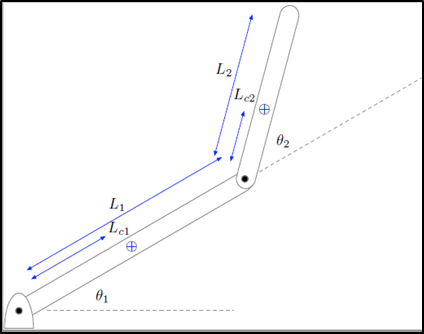

Equations of the system are as provided,

Model equations provided are as below-

$M_{11}\ddot\theta_{1}+M_{12}\ddot\theta_{2}-h\dot\theta_1^2-2h\dot\theta_{1}\dot\theta_{2}+G_1=\tau_1$          ......(1)

$M_{22}\ddot\theta_2+M_{12}\ddot\theta_1+h\dot\theta_1^2+G_2=\tau_2$                        ......(2)

where,


$$M_{11}=m_1L_{c1}^2+I_{c1}+m_2[L_1^2+L_{c2}^2+2L_1L_{c2}cos\theta_2]+I_{c2}$$



$$M_{22}=m_2L_{c2}^2+I_{c2}$$



$$M_{12}=m_2L_1L_{c2}cos\theta_2+m_2L_{c2}^2+I_{c2}$$



$$h=m_2L_1L_{c2}sin\theta_2$$



$$G_1=m_1L_{c1}gcos\theta_1+m_2g[L_{c2}cos(\theta_1+\theta_2)+L_1cos\theta_1]$$



$$G_2=m_2L_{c2}gcos(\theta_1+\theta_2)$$


Reference for the same observed in the book, 'Robot dynamics and control' second edition, Authored by Mark W. Spong, Seth Hutchinson and M. Vidyasagar.

In the chapter dynamics, derivation is provided for planar elbow manipulator from which final equations arrived are same as that of the provided for project. Figure below proved the figure used for derivation in the book.

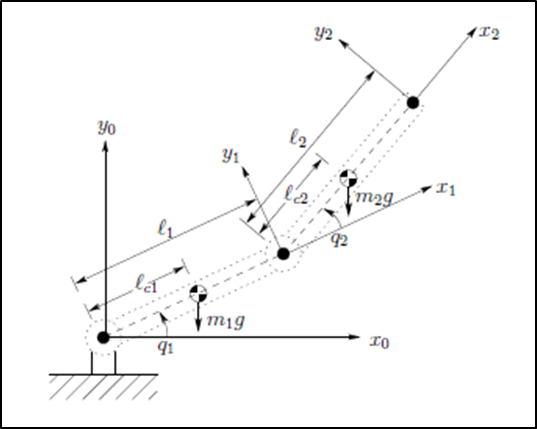

$L_1, L_2$ and $L_{c1}, L_{c2}$ are used in project are denoted by $l_1,l_2$ and $l_{c1},l_{c2}$ and angle $\theta_1$,$\theta_2$ are denoted by angles $q_1,q_2$ in the reference.

after derivation final equation achieved is,


$$d_{11}{\ddot{q_{11}}+d_{12}\ddot{q_2}+c_{121}{\dot{q_2}\dot{q_1}+c_{211}\dot{q_1}\dot{q_2}+c_{221}\dot{q_2}^2}+\phi = \tau_1$$



$$d_{21}\ddot{q_1}+d_{22}\ddot{q_2}+c_{112}{\dot{q_1}^2}+\phi_2 = \tau_2$$


By comparing the terms from the project equation and from reference, equation in form provided for the project can be achieved.

as $d_{11}=M_{11},d_{12}=M_{12},c_{121}=c_{221}=-h$ and$G_1=\phi_1$ for the first equation.

And $d_{21}=M_{22},d_{22}=M_{12},c_{112}=h$ and $G_{2}=\phi_2$ for the second equation.

## **Linearization of the model**

Assuming,


$$C_1=m_1L_{c1}^2+I_{c1}+m_2[L_1^2+L_{c2}^2]+I_{c2}$$



$$C_{2}=m_2L_1L_{c2}$$


Substituting the assumptions in equation (1) and (2) equations of model become,

 
$$C_1\ddot\theta_{1}+2m_2L_1L_{c2}cos\theta_2\ddot\theta_{1}+C_2cos\theta_2\ddot\theta_{2}+M_{22}\ddot\theta_{2}-C_2sin\theta_2\dot\theta_1^2.......$$


$......-2C_2sin\theta_2\dot\theta_{1}\dot\theta_{2}+m_1L_{c1}gcos\theta_1+m_2g[L_{c2}cos(\theta_1+\theta_2)+L_1cos\theta_1]=\tau_1$  ....(3)

$M_{22}\ddot\theta_2+M_{22}\ddot\theta_1+C_2cos\theta_2\ddot\theta_1+C_2sin\theta_2\dot\theta_1^2+m_2L_{c2}gcos(\theta_1+\theta_2)=\tau_2$ ....(4)

for linearization assuming,


$$\theta_1=\theta_{1_0}+\delta\theta_1$$



$$\theta_2=\theta_{2_0}+\delta\theta_2$$



$$\tau_1=\tau_{1_0}+\delta\tau_1$$



$$\tau_2=\tau_{2_0}+\delta\tau_2$$


From the initial conditions available of $\theta_1=0$ and $\theta_2=0$, and at equilibrium assuming $\delta\theta_1=\delta\theta_2=\delta\tau_1=\delta\tau_2=0$

substituting them in equation 3 and 4 we get initial conditions for torque input as,


$$\tau_{1_0}=m_1L_{c1}g+m_2g[L_{c2}+L_1]$$



$$\tau_{2_0}=m_2L_{c2}g$$


 For linearization about $\theta_1=0$ and $\theta_2=0$, substituting$\delta$ terms in equation (3) and (4), we get


$$C_1\ddot\delta\theta_{1}+2C_2cos(\theta_{2_0}+\delta\theta_2)\ddot\delta\theta_{1}+C_2cos(\theta_{2_0}+\delta\theta_2)\ddot\delta\theta_{2}+M_{22}\ddot\delta\theta_{2}-C_2sin(\theta_{2_0}+\delta\theta_2)\dot\delta\theta_1^2-2C_2sin(\theta_{2_0}+\delta\theta_2)\delta\dot\theta_{1}\dot\delta\theta_{2}+.....$$



$$....m_1L_{c1}gcos(\theta_{1_0}+\delta\theta_1)+m_2g[L_{c2}(cos(\theta_{1_0}+\delta\theta_1+\theta_{2_0}+\delta\theta_2)+L_1cos(\theta_{1_0}+\delta\theta_1)]=\tau_{1_0}+\delta\tau_1$$



$$M_{22}\delta\ddot\theta_2+M_{22}\delta\ddot\theta_1+C_2cos(\theta_2+\delta\theta_2)(\delta\ddot\theta_1)+C_2sin(\theta_2+\delta\theta_2)\delta\dot\theta_1^2+m_2L_{c2}gcos(\theta_1+\delta\theta_1+\theta_2+\delta\theta_2)=\tau_2+\delta\tau_2$$


for linearization using Taylor’s expansion we get, 


$$cos(\theta_{2_0}+\delta\theta_2)=(cos(\theta_{2_0}+\delta\theta_2))_{\delta\theta_2=0}-(sin(\theta_{2_0}+\delta\theta_2))_{\delta\theta_2=0}.\delta\theta_2
$$



$$cos(\theta_{2_0}+\delta\theta_2)=cos\theta_{2_0}-sin\theta_{2_0}.\delta\theta_2
$$


substituting initial condition of $\theta_1=0$ and $\theta_2=0$ we get,


$$cos(\theta_{2_0}+\delta\theta_2)=1$$


Using Taylor’s expansion for one variable we get,


$$sin(\theta_{2_0}+\delta\theta_2)=(sin(\theta_{2_0}+\delta\theta_2))_{\delta\theta_2=0}+(cos(\theta_{2_0}+\delta\theta_2))_{\delta\theta_2=0}.\delta\theta_2
$$



$$sin(\theta_{2_0}+\delta\theta_2)=sin\theta_{2_0}+cos\theta_{2_0}.\delta\theta_2
$$


substituting initial condition of $\theta_1=0$ and $\theta_2=0$ we get,


$$sin(\theta_{2_0}+\delta\theta_2)=\delta\theta_2
$$


Using Taylor’s expansion for two variable we get,


$$cos(\theta_{2_0}+\delta\theta_2+\theta_{1_0}+\delta\theta_1)=(cos(\theta_{2_0}+\delta\theta_2+\theta_{1_0}+\delta\theta_1)_{\delta\theta_2=\delta\theta_1=0}-.......$$



$$....(sin(\theta_{2_0}+\delta\theta_2+\theta_{1_0}+\delta\theta_1)_{\delta\theta_2=0}.\delta\theta_2-(sin(\theta_{2_0}+\delta\theta_2+\theta_{1_0}+\delta\theta_1)_{\delta\theta_1=0}.\delta\theta_1
$$



$$cos(\theta_{2_0}+\delta\theta_2+\theta_{1_0}+\delta\theta_1)=cos(\theta_{2_0}+\theta_{1_0})-sin(\theta_{2_0}+\theta_{1_0})-sin(\theta_{2_0}+\theta_{1_0})$$


substituting initial condition of $\theta_1=0$ and $\theta_2=0$ we get,


$$cos(\theta_{2_0}+\delta\theta_2+\theta_{1_0}+\delta\theta_1)=1$$


Using Taylor’s expansion for one variable we get,


$$cos(\theta_{1_0}+\delta\theta_1)=(cos(\theta_{1_0}+\delta\theta_1))_{\delta\theta_1=0}-(sin(\theta_{1_0}+\delta\theta_1))_{\delta\theta_1=0}.\delta\theta_1
$$



$$cos(\theta_{1_0}+\delta\theta_1)=cos\theta_{1_0}-sin\theta_{1_0}.\delta\theta_1
$$


substituting initial condition of $\theta_1=0$ and $\theta_2=0$ we get,


$$cos(\theta_{1_0}+\delta\theta_1)=1$$


By substituting the values obtained after the Taylor’s expansion, equation above become as,


$$C_1\ddot\delta\theta_{1}+2L_1L_{c2}\ddot\delta\theta_{1}+C_2\ddot\delta\theta_{2}+M_{22}\ddot\delta\theta_{2}-C_2\delta\theta_2\dot\delta\theta_1^2-2C_2\delta\theta_2\delta\dot\theta_{1}\dot\delta\theta_{2}+m_1L_{c1}g+
m_2g[L_{c2}+L_1]=\tau_{1_0}+\delta\tau_1$$



$$M_{22}\delta\ddot\theta_2+M_{22}\delta\ddot\theta_1+C_2\delta\ddot\theta_1+C_2\delta\theta_2\delta\dot\theta_1^2+m_2L_{c2}g=\tau_2+\delta\tau_2$$


Considering $\delta\theta_1$and $\delta\theta_2$ small, terms with higher power can be neglected.

By above consideration linearized equation become,


$$(C_1+2C_2)\ddot\delta\theta_{1}+(C_2+M_{22})\ddot\delta\theta_{2}+m_1L_{c1}g+
m_2g[L_{c2}+L_1]=\tau_{1_0}+\delta\tau_1$$



$$M_{22}\delta\ddot\theta_2+(M_{22}+C_2)\delta\ddot\theta_1+m_2L_{c2}g=\tau_2+\delta\tau_2$$


from initial conditions we have,


$$\tau_{1_0}=m_1L_{c1}g+m_2g[L_{c2}+L_1]$$



$$\tau_{2_0}=m_2L_{c2}g$$


hence differential equation for the linearized system at $\theta_1=0$ and $\theta_2=0$ become,

$(C_1+2C_2)\ddot\delta\theta_{1}+(C_2+M_{22})\ddot\delta\theta_{2}=\delta\tau_1$        ......(5)

$M_{22}\delta\ddot\theta_2+(M_{22}+C_2)\delta\ddot\theta_1=\delta\tau_2$                   ......(6)

Linearized equations in terms of the original coefficients are,

$(m_1L_{c1}^2+I_{c1}+m_2[L_1^2+L_{c2}^2]+I_{c2}+2m_2L_1L_{c2})\ddot\delta\theta_{1}+(m_2L_1L_{c2}+m_2L_{c2}^2+I_{c2})\ddot\delta\theta_{2}=\delta\tau_1$   .....(7)

$m_2L_{c2}^2+I_{c2}\delta\ddot\theta_2+(m_2L_{c2}^2+I_{c2}+m_2L_1L_{c2})\delta\ddot\theta_1=\delta\tau_2$                                                      .....(8)

## For State Space Representation

For finding out the values of constant.

% Defining various parameters

% cleanup for earlier data
clearvars       %Clearing the values of variable
close('all')    %Closing earlier graphs    

ald= 2700;  % Density of aluminium in kg/m^3
l1=1;       % Length of link 1 in m provided in project description
l2=0.5;     % Length of link 2 in m provided in project description
lc1=l1/2;   % CG position of link1 in m
lc2=l2/2;   % CG position of link2 in m
r=3e-2;     % Radii of the rod in m provided in project description
theta1=0;   % Value of theta 1 for linearization of system
theta2=0;   % Value of theta 2 for linearization of system

% Finiding values of the mass and other constants.
m1=pi*r^2*l1*ald;        % mass of the rod 1 in kg
m2=pi*r^2*l2*ald;        % mass of the rod 2 in kg
I1=(1/12)*m1*l1^2;       % moment of inertia of rod1 at the cg in kg/m2
I2=(1/12)*m2*l2^2;       % moment of inertia of rod2 at the cg in kg/m2

%Finding values of constanta vailable in the equation
C1=(m1*lc1^2)+I1+I2+(m2*(l1^2+lc2^2));
C2=m2*l1*lc2;
M22=(m2*lc2^2)+I2;

% Calculating coefficents for the terms in equation 5 and 6
coe1=(C1+2*C2);     % Coefficient of delta theta 1 in equation 5
coe2=C2+M22;        % Coefficient of delta theta 2 in equation 5
coe3=M22+C2;        % Coefficient of delta theta 1 in equation 6
coe4=M22;           % Coefficient of delta theta 2 in equation 6

By using the values obtained from above, equation 5 and 6 can be represented as,


$$8.5833\ddot\delta\theta_{1}+1.2723\ddot\delta\theta_{2}=\delta\tau_1$$



$$1.2723\delta\ddot\theta_1+0.3181\delta\ddot\theta_2=\delta\tau_2$$


To generate two equations for $\delta\ddot\theta_1$ and $\ddot\delta\theta_2$


$$ \left[\matrix{8.5883&1.2723 \cr 1.2723&0.3181}\right]\left[\matrix{\delta\ddot\theta_1\cr \delta\ddot\theta_2}\right] = \left[\matrix{1&0 \cr 0&1}\right]\left[\matrix{\delta\tau_1 \cr \delta\tau_2}\right]$$


let us assume, current equation is in the form of


$$E.\vec{\delta\ddot\theta}=F.\vec{\delta\tau}$$


from above equation to obtain the equations in terms of $\delta\ddot\theta_1$ and $\ddot\delta\theta_2$, we have to get


$$\vec{\delta\ddot\theta}=E^{-1}.F.\vec{\delta\tau}$$


% Coefficient for the above equation
E=[coe1 coe2;coe3 coe4];     % matrix E from above equation
F=[1 0;0 1];                 % matrix F from above equation
E1=inv(E);                   % Inverse of matris E as required
E1F=E1*F;                    % Matrix of coefficents of delta tau

From above calculations we get,


$$\left[\matrix{\delta\ddot\theta_1\cr \delta\ddot\theta_1}\right] = \left[\matrix{0.2858&-1.1432 \cr -1.1432&7.7166}\right]\left[\matrix{\delta\tau_1 \cr \delta\tau_2}\right]$$



$$\left[\matrix{\delta\dot\omega\cr \delta\dot{P_i}}\right] = \left[\matrix{0.219284&0.002691 \cr -1424.708&-2.93611}\right]\left[\matrix{\delta{\omega} \cr \delta{P_i}}\right]+\left[\matrix{1.53778&0 \cr 0&1359835.5832}\right]\left[\matrix{\delta{u_s} \cr \delta{u_a}}\right]+\left[\matrix{-0.012869 \cr 0}\right]\delta{P_e}$$


hence final equations for the system become,


$$\delta\ddot\theta_1=0.2858\delta\tau_1-1.1432\delta\tau_2$$



$$\delta\ddot\theta_2=-1.1432\delta\tau_1+7.7166\delta\tau_2$$


to represent in the state space form, assuming


$$x_1=\delta\theta_1$$



$$x_2=\delta\dot\theta_1$$



$$x_3=\delta\theta_2$$



$$x_4=\delta\dot\theta_2$$


from the above considerations we get,

$\dot{x_1}=\dot\delta\theta_1$ gives $\dot{x_1}=x_2$ 

$\dot{x_2}=\ddot\delta\theta_1$ gives $\dot{x_2}=0.2858\delta\tau_1-1.1432\delta\tau_2$

$\dot{x_3}=\dot\delta\theta_2$ gives $\dot{x_3}=x_4$

$\dot{x_4}=\delta\ddot\theta_2$ gives $\dot{x_4}=-1.1432\delta\tau_1+7.7166\delta\tau_2$

and output of the system are as below,

$y_1=\delta\theta_1$ gives $y_1=x_1$

$y_2=\delta\theta_2$ gives $y_2=x_3$

To represent the system in state space form using the state space representation equations,


$$\dot{\vec{x}} = A \vec{x} + B \vec{\tau} $$



$$\dot{\vec{x}} = \left[\matrix{0&1&0&0 \cr0&0&0&0\cr0&0&0&1\cr 0&0&0&0}\right] \vec{x} + \left[\matrix{0&0 \cr 0.2858&-1.1432 \cr 0&0\cr -1.1432&7.7166}\right] \vec{\tau} $$



$$\vec{y} = C \vec{x} + D \vec{\tau}$$



$$\vec{y} = \left[\matrix{1&0&0&0\cr0&0&1&0}\right] \vec{x} + \left[\matrix{0&0\cr0&0}\right] \vec{\tau}$$


% Defining state space representation in matlab
A=[0 1 0 0;0 0 0 0;0 0 0 1;0 0 0 0];        % Define matrix A
B=[0 0;0.2858 -1.1432;0 0;-1.1432 7.7166];  % Define matrix B
C=[1 0 0 0;0 0 1 0];                        % Define matrix C
D=[0 0;0 0];                                % Define matrix D
ics=[0 0 0 0];                              % initial conditions for model

% Getting transfer function for the system from Matlab
[num1, den1]=ss2tf(A,B,C,D,1);              %Transfer function for input tau1
[num2, den2]=ss2tf(A,B,C,D,2);              %Transfer function for input tau2

a1t1 = tf(num1(1,:),den1);                  %Transfer Function of theta1/tau1
a2t1 = tf(num1(2,:),den1);                  %Transfer Function of theta2/tau1
a1t2 = tf(num2(1,:),den2);                  %Transfer Function of theta1/tau2
a2t2 = tf(num2(2,:),den2);                  %Transfer Function of theta2/tau2

From Matlab code transfer function observed to be as below,


$${\delta\theta_1}/{\delta\tau_1} = {0.2858}/{s^2} $$



$${\delta\theta_2}/{\delta\tau_1} = {-1.143}/{s^2} $$



$${\delta\theta_1}/{\delta\tau_2} = {-1.143}/{s^2} $$



$${\delta\theta_2}/{\delta\tau_2} = {7.717}/{s^2} $$


### Control Design Approach

For control design two approaches were used, one was with the coupled system using the state space representation format and another considering two links independent of each other and using the transfer function for ${\delta\theta_1}/{\delta\tau_1}$ and ${\delta\theta_2}/{\delta\tau_2}$. With PID controller available in Simulink, coupled between the decoupled systems transfer functions input and output, it was tuned for underdamped system, by adjusting the rise time and settling time for proper response from system, once values finalised, calculated the values of gain for proportional and derivative gain and added in the system, then fine tunned model to get the resose with reduced fluctuations, while continuously checking the PID output to not go above limit of 1N-m for both the values.

Figure below shows the simulink model details prepared for the same.

On the left is the required input with ${1^o}$ to ${10^o}$ ramping of both the angles in 4sec. In the model area highlighted by name decoupled system below shows control logic used for the decoupled system with individual transfer functions and area highlighted by the coupled system gives the model with the state space representation. PID gain values from the decoupled system were supplied to the coupled system and response observed to check effect of the variation in the decoupling the system.

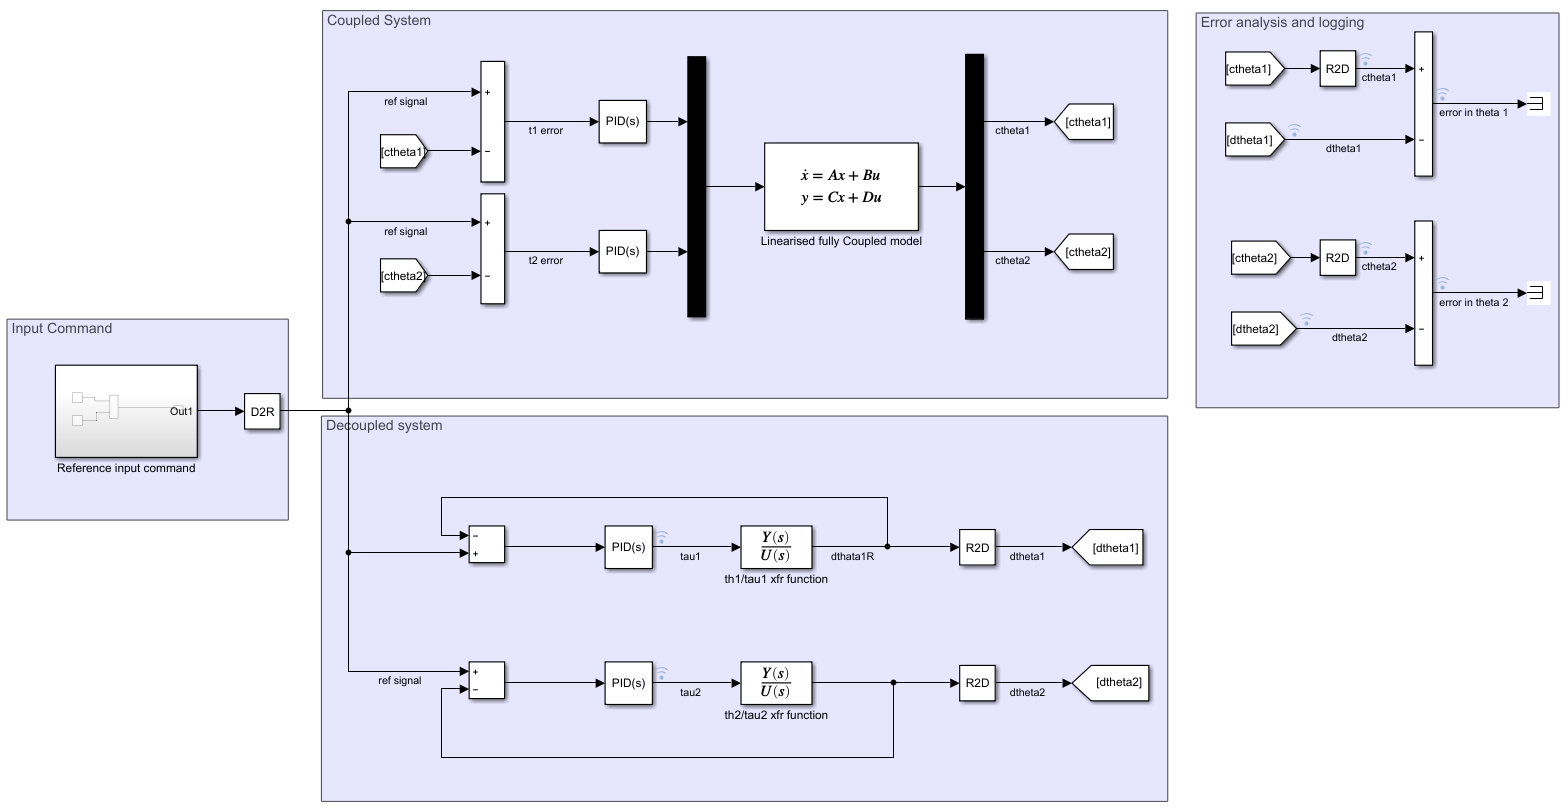

% Opening Simulink Model for function analysis

mName='p1Sim';

open_system (mName)
Simulink.sdi.clear              % to  Clear Simulink previous data

tFinal=20;                      % Time of simulation
tSample=0.001;                  % integration step time

% Defining paramaters for the refernce command
ms.theta1 = 10;                 % Value of theta1
ms.theta2 = 10;                 % Value of theta2
ms.T0 = 0;                      % Start Time in s
ms.T1 = 4;                      % Ramp up/down time in s
ms.T2 = 4;                      % Time after which ramp ramp is zero

**For plotting the results**

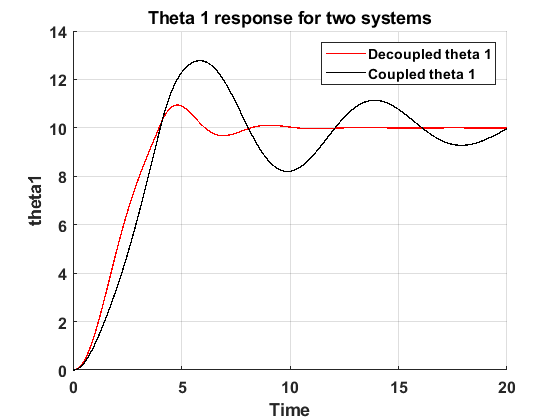

% Configure the logging info in the model and run it
sOut = sim('p1Sim','SignalLoggingName','sdat');

% Saving requirememnt
SAVEME=0;               %set1 for saving the graph or 0 elsewise
%%Plotting the results
% Definig indices from the Simulink
dtheta1=1;              % Theta 1 from decoupled system
dtheta2=2;              % Theta 2 from decoupled system
ctheta1=5;              % Theta 1 from coupled system
ctheta2=6;              % Theta 2 from coupled system
tau1out=3;              % Tau 1 output from the PID of decoupled system
tau2out=4;              % Tau 1 output from the PID of decoupled system

%Plot Parameters
LW=1;                                        %linewidth
FS= 12;                                      %Fontsize
FILETYPE= '-depsc';                          %graphic file type
FNAME1 = 'Coupled vs Decoupled (theta1)';    %filename for theta 1 response check
FNAME2 = 'Coupled vs Decoupled (theta2)';    %filename for theta 2 response check
FNAME3 = 'Coupled vs Decoupled (theta2)';

%Grab data fro plotting from simulink
t = sOut.sdat{dtheta1}.Values.Time;         % Values of time for responses
dt1=sOut.sdat{dtheta1}.Values.Data;         %Decoupled system theta 1 response
dt2=sOut.sdat{dtheta2}.Values.Data;         %Decoupled system theta 2 response
ct1=sOut.sdat{ctheta1}.Values.Data;         %Coupled system theta 1 response
ct2=sOut.sdat{ctheta2}.Values.Data;         %Coupled system theta 2 response
ta1=sOut.sdat{tau1out}.Values.Data;         % Tau 1 value from decoupled theta1
ta2=sOut.sdat{tau2out}.Values.Data;         % Tau 2 value from decoupled theta2\

%Defining plot ids based on data required
id1=1;                                        %plot id for theta 1comparison
id2=2;                                        %plot id for theta 2comparison  
id3=3;                                        %plot id for tau value check

% For plot 1  
h(id1).fig =figure(id1);                                    % makeing figure
h(id1).axs =axes;                                           % Make axies
h(id1).ln(1)=line(t,dt1,'Color','r');                       % decoupled theta 1
h(id1).ln(2)=line(t,ct1,'Color','k');                       % coupled theta 1
h(id1).xlb = xlabel('Time');                                % Xlabel for plot1
h(id1).ylb = ylabel('theta1');                              % Ylabel for plot1
h(id1).leg = legend('Decoupled theta 1','Coupled theta 1'); % legends
h(id1).tit = title('Theta 1 response for two systems');     % title for plot
%Plot formatting
for i=1:length(h(id1).ln)                                   % Setting linewidth for first plot
    h(id1).ln(i).LineWidth = LW;
end
h(id1).axs.FontSize   = FS;                                 % axis font size for first plot
h(id1).axs.FontWeight = 'Bold';                             % Set axis type for first plot
grid;

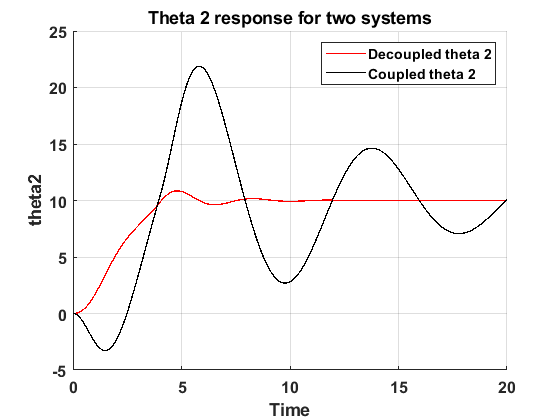


% For plot 2
h(id2).fig  = figure(id2);                                  % makeing figure
h(id2).axs  = axes;                                         % Make axies
h(id2).ln(1)=line(t,dt2,'Color','r');                       % dcoupled theta 2
h(id2).ln(2)=line(t,ct2,'Color','k');                       % coupled theta 2
h(id2).xlb  = xlabel('Time');                               % Xlabel for plot2
h(id2).ylb  = ylabel('theta2');                             % Ylabel for plot2
h(id2).leg  = legend('Decoupled theta 2','Coupled theta 2');% legends
h(id2).tit  = title('Theta 2 response for two systems');    %title for plot2

%Plot formatting
for i=1:length(h(id2).ln)                                   % Setting linewidth for second plot
    h(id2).ln(i).LineWidth = LW;
end
h(id2).axs.FontSize   = FS;                                 % axis font size for second plot
h(id2).axs.FontWeight = 'Bold';                             % Set axis type for second plot
grid;

As from the above two graphs, with decoupled system for both angles values observed to achieve the input with minor fluctuations till the system settle down. But when same inputs were provided to the state space model of the coupled system there observed to be large fluctuations for both $\delta\theta_1$ and $\delta\theta_2$ values, though the system reached at the value of $10^o$ at the end of the 4 seconds, it continues to rise above the value and takes large time to settle down. Behavior mainly seem to be effect of the another torque than considered (eg. for $\delta\theta_1$ we have considered only $\delta\tau_1$ in the system), as the final equation of the system provided by equations (7) and (8), informs that angle output is dependent on the both the torques.

For the decoupled system, we have ignored the one transfer function affecting each $\delta\theta$ values, which is considered in the state space representation of coupled system, hence the difference between the output observed. More variations observed in the $\delta\theta_2$ which is angle for the second link as the motion from the first link is providing it with initial motion which is not being considered in the decoupled system and with the command to move it to the required angle is getting higher error causing the large fluctuation, whereas for the link 1 variations can be attributed as, for motion of the link 1 extra opposing motion it require to overcome at the end of link is considered in the decoupled model, hence larger input is required and as same is not considered in the decoupled, there observed to be large fluctuations in the system but are less than observed in the $\delta\theta_2$.   

If the final system is prepared with the assumption as a decoupled system, it will be difficult to achieve required results in the given time as system will continue to vibrate for more time than anticipated to become stable and vibrations will also be higher. One approach to linearize the system with given model can be to utilize the second transfer function in the decoupled system to obtain the required values.

In the initial equation for linearization we are considering only $\delta\tau$ terms, but to bring system in the horizontal position we will have to provide additional torque which will bring the system in required position and our linearized system can fine tune about that point. By changing the terms of $\delta\tau$ back to terms in $\tau$ and $\tau_0$, we will get the factor of gravity affecting on the system when it is horizontal state and it will try to bring system down to vertically suspended position, hence equal amount of torque should be provided to keep system in that state.

Block diagram representation of the system can be as shown below.

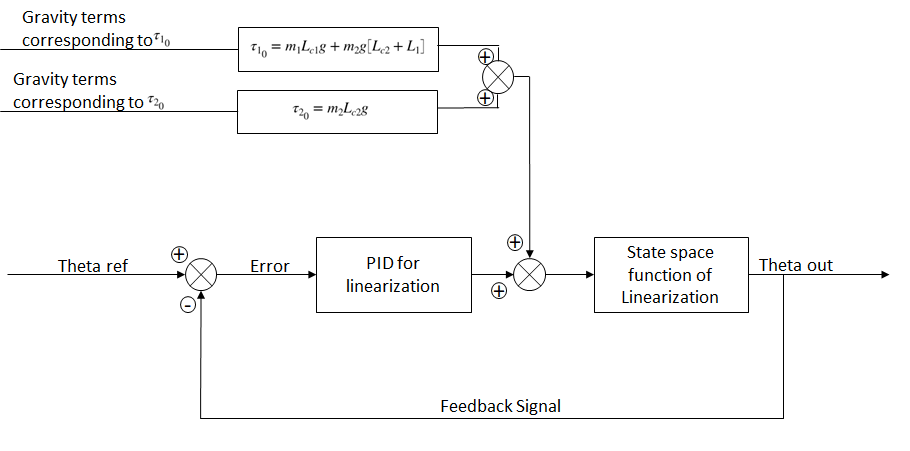

Figure below is to verify the output torque is not exceeding the limit of 1Nm in both the cases.

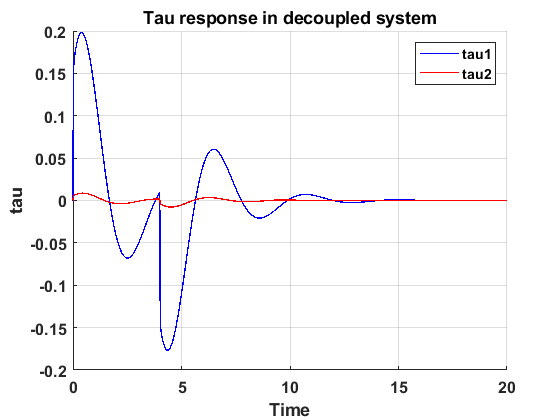

% For plot 3 of tau value check
h(id3).fig =figure(id3);                                    % makeing figure
h(id3).axs =axes;                                           % Make axies
h(id3).ln(1)=line(t,ta1,'Color','b');                       % tau1
h(id3).ln(2)=line(t,ta2,'Color','r');                       % tau2
h(id3).xlb = xlabel('Time');                                % Xlabel for plot3
h(id3).ylb = ylabel('tau');                                 % Ylabel for plot3
h(id3).leg = legend('tau1','tau2');                         % legends
h(id3).tit = title('Tau response in decoupled system');     %title for plot

%Plot formatting
for i=1:length(h(id3).ln)                                   % Setting linewidth for third plot
    h(id3).ln(i).LineWidth = LW;
end
h(id3).axs.FontSize   = FS;                                 % axis font size for third plot
h(id3).axs.FontWeight = 'Bold';                             % Set axis type for third plot
grid;

% Saving the figure
if SAVEME==1
    sfname = [FNAME1,'Plots'];                              % Plot1 details
    print(h(id1).fig,sfname,FILETYPE);                      % save the figure
    sfname = [FNAME2,'Plots'];                              % Plot2 details
    print(h(id2).fig,sfname,FILETYPE);                      % save the figure
    sfname = [FNAME3,'Plots'];                              % Plot3 details
    print(h(id3).fig,sfname,FILETYPE);                      % Save the figure
end